# Quarter wave plate

A quarter-wave plate is a bi-refringent material cut to a specific thickness.  The bi-refringence produces two rays: ordinary and extraordinary.  These rays are polarized at 90 deg difference, so that we can treat one as oscillating in the x- and the other in the y-direction.

The bi-refringent material has different index of refraction (speed of light) for the two rays. If we cut the thickness of the plate correctly, then one is delayed compared to the other.  By setting the thickness precisely, we can treat one in sine phase and the other in cosine phase.

This figure produced in this script shows the two rays oscillating in the x- and y-directions as the red markers. The sum of the two is shown as the end point on the black line (whose origin is at 0,0). Notice that the amplitude is constant. The direction changes around in a circle over time.  Hence the quarter-wave plate produces a ray with circular polarization.

## Set up the two waves

% Oscillating wave representing a ray polarized in the x-direction
t = (0:255)/256;
f = 3;
ordinaryW = sin(2*pi*f*t);
% plot(t,ordinaryW);

% Oscillating wave representing polarization in the y-direction
extraordinaryW = cos(2*pi*f*t);
% plot(t,extraordinaryW);

total = [ordinaryW(:), extraordinaryW(:)];

## Make the movie

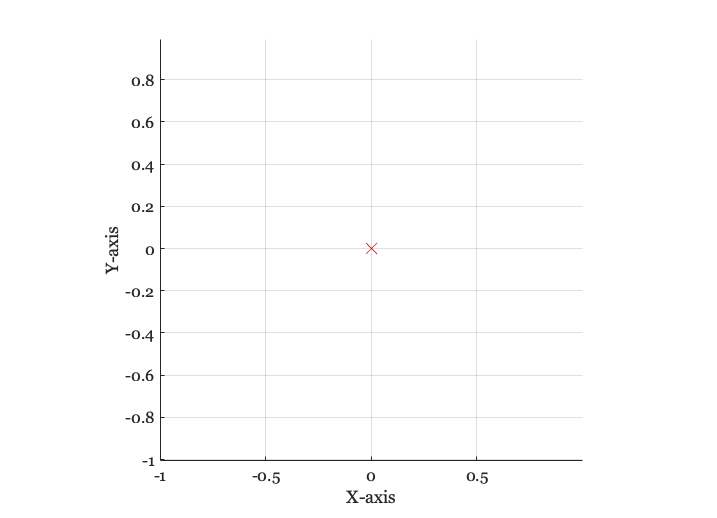

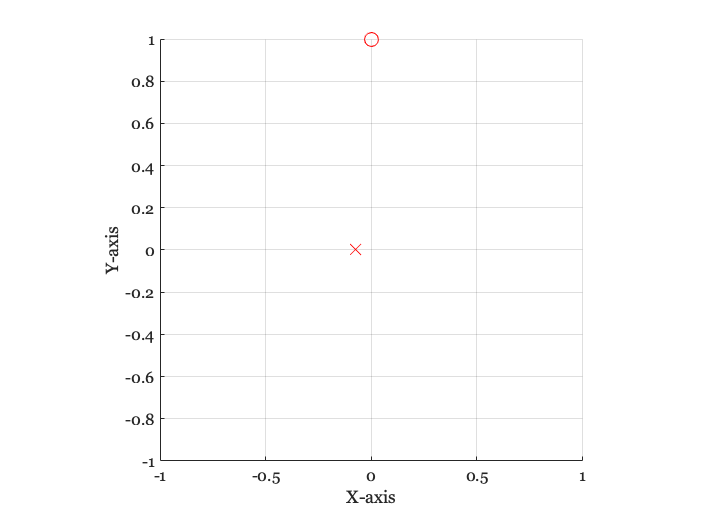

ieNewGraphWin; axis equal; grid on;
xlabel('X-axis'); ylabel('Y-axis');

% For each moment in time, plot the individual rays as red markers and
% the sum as the black line.
for ii=1:numel(t)
    cla;   
    l = line([0 total(ii,1)],[0 total(ii,2)],...
        'Color','k','LineWidth',2); hold on;
    plot(total(ii,1),0,'rx','MarkerSize',14); hold on;
    plot(0,total(ii,2),'ro','MarkerSize',14); hold on;
    set(gca,'xlim',[-1 1],'ylim',[-1 1]);
    pause(0.05); delete(l);
end

## END